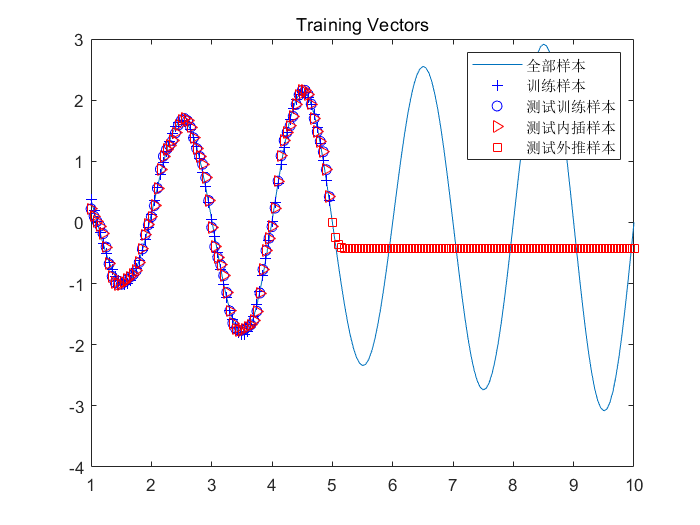

clf;
rng(5);
rng;

P = 1:.05:10;
T = exp(-P)+(P.^0.5).*sin(pi*P);
train_d = P(1:80);              %训练用数据
train_l = T(1:80);              %训练用label
trian_iner = P(1:80);           %内插训练数据
test_extra = P(81:181);         %外推测试数据
%设置训练超参数
maxiter = 2000;         %最大迭代次数
eta = 0.06;              %学习率
mc = 0.8;               %动量因子
eb = 0.001;              %误差容限度
nHi = 15;                % 隐藏层数目
%建立网络
net.trainParam.epochs = maxiter;
net.trainParam.goal = eb;
net.trainParam.lr = eta;
net.trainParam.mc = mc;
net=feedforwardnet(nHi);
net.trainFcn = 'trainbfg';
%训练网络
[net,tr] = train(net, train_d, train_l);
train_out = sim(net, train_d);
trian_inter_out = sim(net, trian_iner);
test_extra_out = sim(net, test_extra);

plot(P,T);
hold on;
plot(train_d, train_l,'+','MarkerEdgeColor','b');
plot(train_d,train_out,'o', 'MarkerEdgeColor','b');
plot(trian_iner, trian_inter_out,'>','MarkerEdgeColor','r');
plot(test_extra, test_extra_out,'s','MarkerEdgeColor','r');
legend('全部样本', '训练样本', '测试训练样本', '测试内插样本', '测试外推样本');
title('Training Vectors');